clc
clear
%%DECLARACION DE VARIABLES
peso=[165,167,180,155,212,175,190,210,200,149,158,169,170,172,159,168,174,183,215,195,180,143,240,235,192,187];
PS=[130,133,150,128,151,146,150,140,148,125,133,135,150,153,128,132,149,158,150,163,156,124,170,165,160,159];

%%ORDENAR LOS DATOS
peso_or=sort(peso)

peso_or =    143   149   155   158   159   165   167   168   169   170   172   174   175   180   180   183   187   190   192   195   200   210   212   215   235   240


PS_or=sort(PS)

PS_or =    124   125   128   128   130   132   133   133   135   140   146   148   149   150   150   150   150   151   153   156   158   159   160   163   165   170



%DATOS INICIALIZACION
n=length(peso)

n = 26

min(peso)

ans = 143

max(peso)

ans = 240

rpeso=range(peso)

rpeso = 97


n=length(PS)

n = 26

min(PS)

ans = 124

max(PS)

ans = 170

rPS=range(PS)

rPS = 46


K=6

K = 6


lpeso=rpeso/K

lpeso = 16.1667

Lpeso=ceil(lpeso)

Lpeso = 17


lPS=rPS/K

lPS = 7.6667

LPS=ceil(lPS)

LPS = 8


%MEDIDAS DE TENDENCIA CENTRAL 

peso_media=mean(peso)

peso_media = 182.4231

peso_mediana=median(peso_or)

peso_mediana = 177.5000

peso_moda=mode(peso)

peso_moda = 180

peso_varianza=var(peso)

peso_varianza = 612.4938

peso_desviacion=std(peso)

peso_desviacion = 24.7486

peso_cvariacion=(peso_desviacion/peso_media)

peso_cvariacion = 0.1357


PS_media=mean(PS)

PS_media = 145.6154

PS_mediana=median(PS_or)

PS_mediana = 149.5000

PS_moda=mode(PS)

PS_moda = 150

PS_varianza=var(PS)

PS_varianza = 180.0862

PS_desviacion=std(PS)

PS_desviacion = 13.4196

PS_cvariacion=PS_desviacion/PS_media

PS_cvariacion = 0.0922


%MARCAS
m_peso1=151.5;
m_peso=[m_peso1 m_peso1+Lpeso m_peso1+(2*Lpeso) m_peso1+(3*Lpeso) m_peso1+(4*Lpeso) m_peso1+(5*Lpeso)]

m_peso =   151.5000  168.5000  185.5000  202.5000  219.5000  236.5000


marca_peso=m_peso';

m_PS1=128;
m_PS=[m_PS1 m_PS1+LPS m_PS1+(2*LPS) m_PS1+(3*LPS) m_PS1+(4*LPS) m_PS1+(5*LPS)]

m_PS =    128   136   144   152   160   168


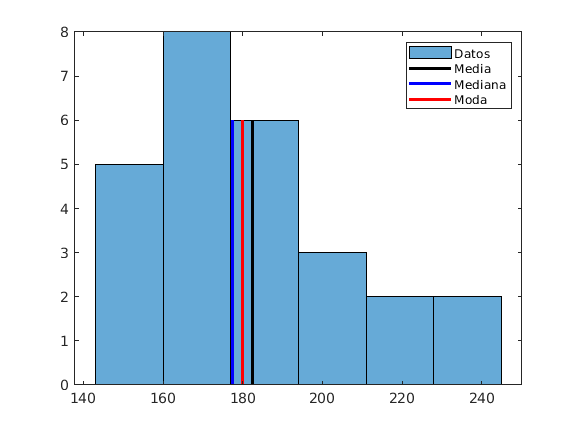

marca_PS=m_PS';

%HISTOGRAMAS CON MEDIDAS DE TENDENCIA Y ESTABLECER DATOS DE FRECUENSIAS
intervalo_peso=[143:17:245];
h_peso=histogram(peso,intervalo_peso);
frecuencia_peso=h_peso.Values;
hold on
plot([peso_media peso_media],[0 6],'black','LineWidth',2)
plot([peso_mediana peso_mediana],[0 6],'b','LineWidth',2)
plot([peso_moda peso_moda],[0 6],'r','LineWidth',2)
legend('Datos','Media', 'Mediana','Moda')  
hold off

fa_peso=frecuencia_peso';
fr_peso=fa_peso/n;
F_peso=cumsum(fa_peso);
Fr_peso=F_peso/n;


intervalo_PS=[124:8:172];
h_PS=histogram(PS,intervalo_PS)

h_PS =   Histogram with properties:

             Data: [130 133 150 128 151 146 150 140 148 125 133 135 150 153 128 132 149 158 150 163 156 124 170 165 160 159]
           Values: [5 4 2 8 5 2]
          NumBins: 6
         BinEdges: [124 132 140 148 156 164 172]
         BinWidth: 8
        BinLimits: [124 172]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


frecuencia_PS=h_PS.Values

frecuencia_PS =      5     4     2     8     5     2


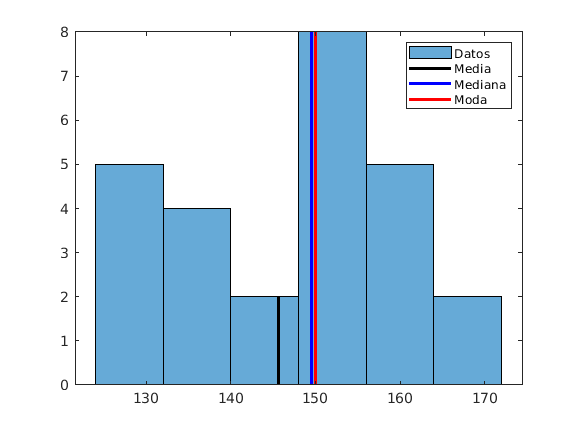

hold on
plot([PS_media PS_media],[0 2],'black','LineWidth',2)
plot([PS_mediana PS_mediana],[0 8],'b','LineWidth',2)
plot([PS_moda PS_moda],[0 8],'r','LineWidth',2)
legend('Datos','Media', 'Mediana','Moda')  
hold off

fa_PS=frecuencia_PS';
fr_PS=fa_PS/n;
F_PS=cumsum(fa_PS);
Fr_PS=F_PS/n;

table(marca_peso,fa_peso,fr_peso,F_peso,Fr_peso,marca_PS,fa_PS,fr_PS,F_PS,Fr_PS)

ans = 6×10 table
    marca_peso    fa_peso    fr_peso     F_peso    Fr_peso    marca_PS    fa_PS     fr_PS      F_PS     Fr_PS 
    __________    _______    ________    ______    _______    ________    _____    ________    ____    _______

      151.5          5        0.19231       5      0.19231      128         5       0.19231      5     0.19231
      168.5          8        0.30769      13          0.5      136         4       0.15385      9     0.34615
      185.5          6        0.23077      19      0.73077      144         2      0.076923     11     0.42308
      202.5          3        0.11538      22      0.84615      152         8       0.3

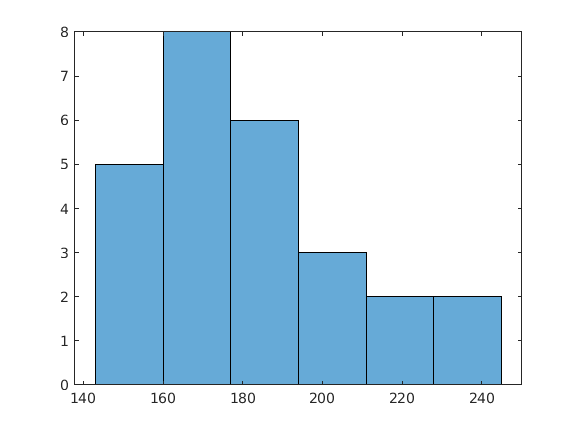

%GRAFICAS PESO

intervalo_peso=[143:17:245];
h_peso=histogram(peso,intervalo_peso);

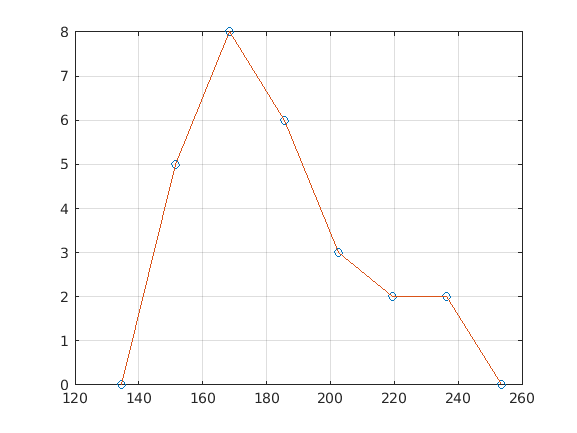

%poligonos
frecuencia_peso=h_peso.Values;
mp_peso=[151.5-17 m_peso 236.5+17];
fp_peso=[0 frecuencia_peso 0];
figure
plot(mp_peso,fp_peso,'o',mp_peso,fp_peso)
grid on

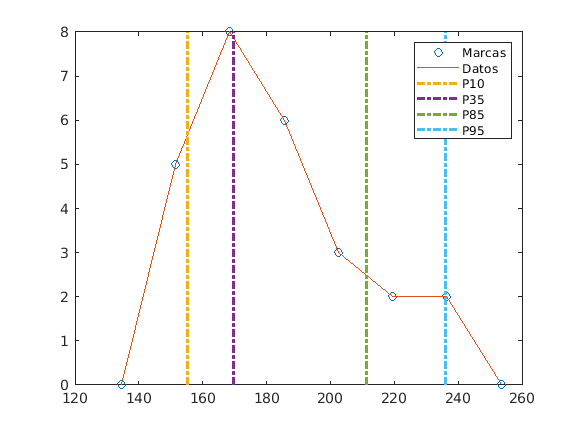



p10_p=prctile(peso,10);
p35_p=prctile(peso,35);
p85_p=prctile(peso,85);
p95_p=prctile(peso,95);
frecuencia_peso=h_peso.Values;
mp_peso=[151.5-17 m_peso 236.5+17];
fp_peso=[0 frecuencia_peso 0];
figure
plot(mp_peso,fp_peso,'o',mp_peso,fp_peso)
hold on
plot([p10_p p10_p],[0 8],'-.','LineWidth',2)
plot([p35_p p35_p],[0 8],'-.','LineWidth',2)
plot([p85_p p85_p],[0 8],'-.','LineWidth',2)
plot([p95_p p95_p],[0 8],'-.','LineWidth',2)
legend('Marcas','Datos','P10', 'P35','P85','P95')  
hold off




d2_p=prctile(peso,20);
d4_p=prctile(peso,40);
d7_p=prctile(peso,70);
frecuencia_peso=h_peso.Values;
mp_peso=[151.5-17 m_peso 236.5+17];
fp_peso=[0 frecuencia_peso 0];
figure
plot(mp_peso,fp_peso,'o',mp_peso,fp_peso)
hold on
plot([d2_p d2_p],[0 8],'-.','LineWidth',2)
plot([d4_p d4_p],[0 8],'-.','LineWidth',2)
plot([d7_p d7_p],[0 8],'-.','LineWidth',2)
legend('Marcas','Datos','D2', 'D4','D7')  
hold off





q1_p=prctile(peso,25);
q2_p=prctile(peso,50);
q3_p=prctile(peso,75);
frecuencia_peso=h_peso.Values;
mp_peso=[151.5-17 m_peso 236.5+17];
fp_peso=[0 frecuencia_peso 0];
figure
plot(mp_peso,fp_peso,'o',mp_peso,fp_peso)
hold on
plot([q1_p q1_p],[0 8],'-.','LineWidth',2)
plot([q2_p q2_p],[0 8],'-.','LineWidth',2)
plot([q3_p q3_p],[0 8],'-.','LineWidth',2)
legend('Marcas','Datos','Q1', 'Q2','Q3')  
hold off


%torta
figure
explode = [0 1 0 0 0 0]

explode =      0     1     0     0     0     0


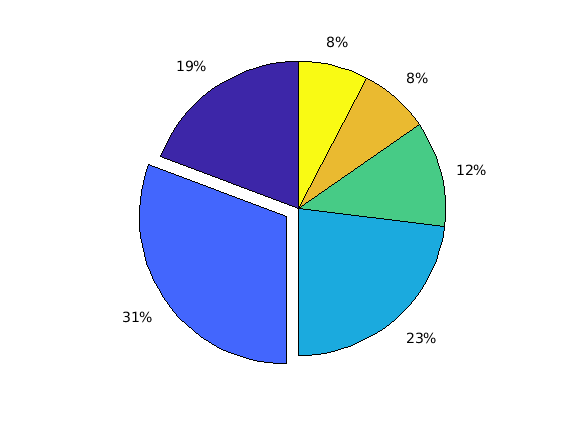

pie(frecuencia_peso,explode)

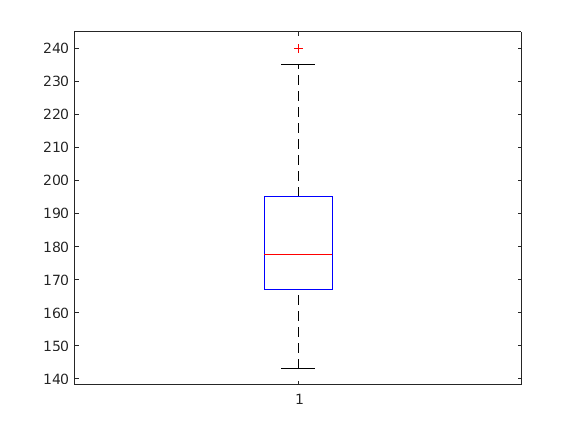


%CAJA Y BIGOTE
boxplot(peso_or)


%GRAFICAS PS

intervalo_PS=[124:8:172];
h_PS=histogram(PS,intervalo_PS);

%poligonos
frecuencia_PS=h_PS.Values;
mp_PS=[128-8 m_PS 168+8];
fp_PS=[0 frecuencia_PS 0];
figure
plot(mp_PS,fp_PS,'o',mp_PS,fp_PS)
grid on



p10_P=prctile(PS,10);
p35_P=prctile(PS,35);
p85_P=prctile(PS,85);
p95_P=prctile(PS,95);
frecuencia_PS=h_PS.Values;
mp_PS=[128-8 m_PS 168+8];
fp_PS=[0 frecuencia_PS 0];
figure
plot(mp_PS,fp_PS,'o',mp_PS,fp_PS)
hold on
plot([p10_P p10_P],[0 8],'-.','LineWidth',2)
plot([p35_P p35_P],[0 8],'-.','LineWidth',2)
plot([p85_P p85_P],[0 8],'-.','LineWidth',2)
plot([p95_P p95_P],[0 8],'-.','LineWidth',2)
legend('Marcas','Datos','P10', 'P35','P85','P95')  
hold off




d2_P=prctile(PS,20);
d4_P=prctile(PS,40);
d7_P=prctile(PS,70);
frecuencia_PS=h_PS.Values;
mp_PS=[128-8 m_PS 168+8];
fp_PS=[0 frecuencia_PS 0];
figure
plot(mp_PS,fp_PS,'o',mp_PS,fp_PS)
hold on
plot([d2_P d2_P],[0 8],'-.','LineWidth',2)
plot([d4_P d4_P],[0 8],'-.','LineWidth',2)
plot([d7_P d7_P],[0 8],'-.','LineWidth',2)
legend('Marcas','Datos','D2', 'D4','D7')  
hold off





q1_P=prctile(PS,25);
q2_P=prctile(PS,50);
q3_P=prctile(PS,75);
frecuencia_PS=h_PS.Values;
mp_PS=[128-8 m_PS 168+8];
fp_PS=[0 frecuencia_PS 0];
figure
plot(mp_PS,fp_PS,'o',mp_PS,fp_PS)
hold on
plot([q1_P q1_P],[0 8],'-.','LineWidth',2)
plot([q2_P q2_P],[0 8],'-.','LineWidth',2)
plot([q3_P q3_P],[0 8],'-.','LineWidth',2)
legend('Marcas','Datos','Q1', 'Q2','Q3')  
hold off



%torta
figure
explode = [0 0 0 1 0 0]

explode =      0     0     0     1     0     0


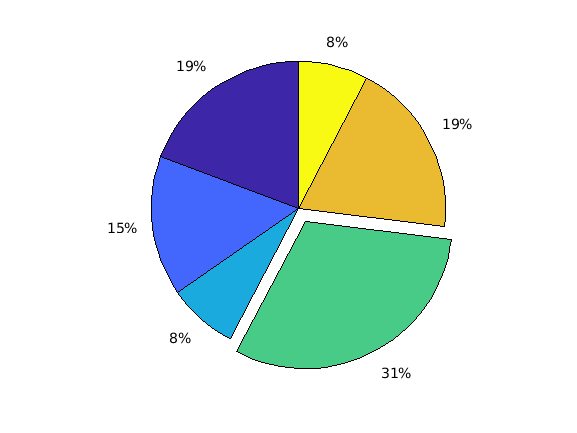

pie(frecuencia_PS,explode)


%CAJA Y BIGOTE

boxplot(PS_or)